dengueTable=tabularTextDatastore('dengue.csv');

dengueTable.VariableNames([1 2 3 4 5 6 7 8 9 10])={'dieaese' 'year' 'month' 'city' 'area' 'gender' 'imported' 'age' 'cases' 'station'}

dengueTable =   TabularTextDatastore with properties:

                      Files: {
                             'C:\Users\Lin\Desktop\MATLAB\dengue.csv'
                             }
               FileEncoding: 'UTF-8'
   AlternateFileSystemRoots: {}
      PreserveVariableNames: false
          ReadVariableNames: true
              VariableNames: {'dieaese', 'year', 'month' ... and 13 more}
             DatetimeLocale: en_US

  Text Format Properties:
             NumHeaderLines: 0
                  Delimiter: ','
               RowDelimiter: '\r\n'
             TreatAsMissing: ''
               MissingValue: NaN

  Advanced Text Format Properties:
            TextscanFormats: {'%q', '%f', '%f' ... and 13 more}
                   TextType: 'char'
         ExponentCharacters: 'eEdD'
               CommentStyle: ''
                 Whitespace: ' \b\t'
    MultipleDelimitersAsOne: false



dengueTallArray=tall(dengueTable);

k=gather(strcmp(dengueTallArray.city,{'高雄市'}));

Evaluating tall expression using the Local MATLAB Session:
- Pass 1 of 1: Completed in 0.95 sec
Evaluation completed in 1.5 sec


t=gather(strcmp(dengueTallArray.city,{'台南市'}));

Evaluating tall expression using the Local MATLAB Session:
- Pass 1 of 1: Completed in 0.2 sec
Evaluation completed in 0.3 sec



kaoArray=gather(dengueTallArray(gather(k),:));

Evaluating tall expression using the Local MATLAB Session:
- Pass 1 of 2: Completed in 0.42 sec
- Pass 2 of 2: Completed in 0.39 sec
Evaluation completed in 1.9 sec


taiArray=gather(dengueTallArray(gather(t),:));

Evaluating tall expression using the Local MATLAB Session:
- Pass 1 of 2: Completed in 0.16 sec
- Pass 2 of 2: Completed in 0.15 sec
Evaluation completed in 0.54 sec



weatherTable=tabularTextDatastore('weatherAll.csv');
weatherTallArray=tall(weatherTable);

for i=2009:2020
    for j=1:12
        x=find(kaoArray.year==i & kaoArray.month==j);
        n=sum(gather(kaoArray.cases(x)));
        kaoCase(i-2008,j)=n;
    end
end

for i=2009:2020
    for j=1:12
        x=find(taiArray.year==i & taiArray.month==j);
        n=sum(gather(taiArray.cases(x)));
        taiCase(i-2008,j)=n;
    end
end

kaoWeather=gather(weatherTallArray(find(ismember(weatherTallArray.name,'高雄')),:));

Evaluating tall expression using the Local MATLAB Session:
- Pass 1 of 4: Completed in 0.089 sec
- Pass 2 of 4: Completed in 0.18 sec
- Pass 3 of 4: Completed in 0.33 sec
- Pass 4 of 4: Completed in 0.14 sec
Evaluation completed in 0.86 sec


for i=1:12
    for j=1:12
        x=find(kaoWeather.year==i+2008 & kaoWeather.month==j);
        n=gather(kaoWeather.temperature(x));
        if isempty(n)
            n=0;
        end
        kaoTem(i,j)=n;
    end
end

taiWeather=gather(weatherTallArray(find(ismember(weatherTallArray.name,'臺南')),:));

Evaluating tall expression using the Local MATLAB Session:
- Pass 1 of 4: Completed in 0.045 sec
- Pass 2 of 4: Completed in 0.12 sec
- Pass 3 of 4: Completed in 0.14 sec
- Pass 4 of 4: Completed in 0.088 sec
Evaluation completed in 0.46 sec


for i=1:12
    for j=1:12
        x=find(taiWeather.year==i+2008 & taiWeather.month==j);
        n=gather(taiWeather.temperature(x));
        if isempty(n)
            n=0;
        end
        taiTem(i,j)=n;
    end
end
xvalues={'1' '2' '3' '4' '5' '6' '7' '8' '9' '10' '11' '12'};
yvalues={ '2009', '2010', '2011', '2012', '2013', '2014', '2015', '2016', '2017', '2018', '2019', '2020'};
h1=heatmap(xvalues,yvalues,kaoCase)

h1 =   HeatmapChart with properties:

        XData: {12×1 cell}
        YData: {12×1 cell}
    ColorData: [12×12 double]

  Show all properties


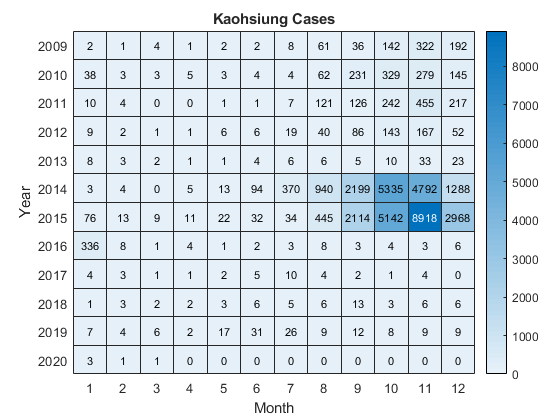

h1.Title='Kaohsiung Cases';
h1.XLabel='Month';
h1.YLabel='Year';


xvalues={'1' '2' '3' '4' '5' '6' '7' '8' '9' '10' '11' '12'};
yvalues={ '2009', '2010', '2011', '2012', '2013', '2014', '2015', '2016', '2017', '2018', '2019', '2020'};
h2=heatmap(xvalues,yvalues,fix(kaoTem))

h2 =   HeatmapChart with properties:

        XData: {12×1 cell}
        YData: {12×1 cell}
    ColorData: [12×12 double]

  Show all properties


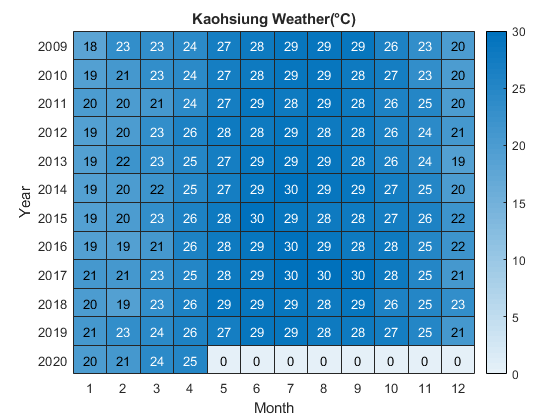

h2.Title='Kaohsiung Weather(°C)';
h2.XLabel='Month';
h2.YLabel='Year';


xvalues={'1' '2' '3' '4' '5' '6' '7' '8' '9' '10' '11' '12'};
yvalues={ '2009', '2010', '2011', '2012', '2013', '2014', '2015', '2016', '2017', '2018', '2019', '2020'};
h3=heatmap(xvalues,yvalues,taiCase)

h3 =   HeatmapChart with properties:

        XData: {12×1 cell}
        YData: {12×1 cell}
    ColorData: [12×12 double]

  Show all properties


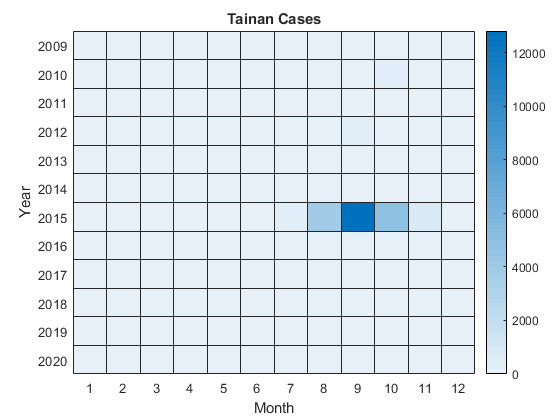

h3.Title='Tainan Cases';
h3.XLabel='Month';
h3.YLabel='Year';


xvalues={'1' '2' '3' '4' '5' '6' '7' '8' '9' '10' '11' '12'};
yvalues={ '2009', '2010', '2011', '2012', '2013', '2014', '2015', '2016', '2017', '2018', '2019', '2020'};
h4=heatmap(xvalues,yvalues,fix(taiTem))

h4 =   HeatmapChart with properties:

        XData: {12×1 cell}
        YData: {12×1 cell}
    ColorData: [12×12 double]

  Show all properties


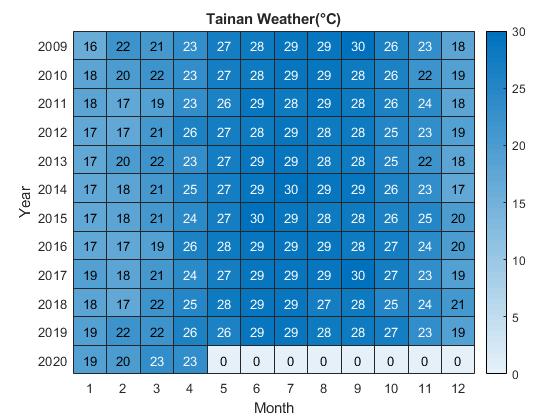

h4.Title='Tainan Weather(°C)';
h4.XLabel='Month';
h4.YLabel='Year';